# MGRIT example

Here I wrote a very simple example for MGRIT


$$\frac{\partial u}{\partial t} = t,\quad u(0) = 1$$



$$u_{i+1}=u_i + 1$$



$$\Phi(u_i) = u_i, \quad g_i = 1, \quad\forall i\in[0, T]$$


% Define the ratio of coarse grid
fc_ratio = 4;

[A, u, g] = gen_trivial(10);
disp(A)

   (1,1)        1
   (2,1)       -1
   (2,2)        1
   (3,2)       -1
   (3,3)        1
   (4,3)       -1
   (4,4)        1
   (5,4)       -1
   (5,5)        1
   (6,5)       -1
   (6,6)        1
   (7,6)       -1
   (7,7)        1
   (8,7)       -1
   (8,8)        1
   (9,8)       -1
   (9,9)        1
  (10,9)       -1
  (10,10)       1



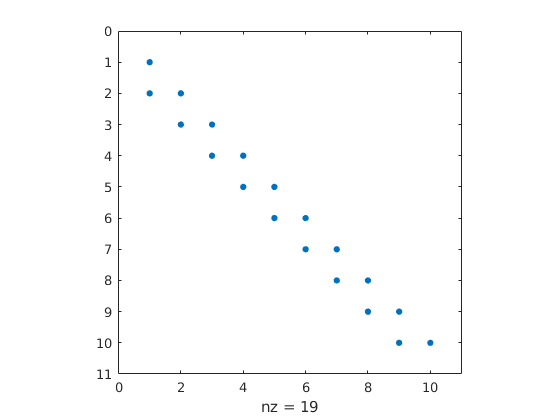

spy(A)

disp(g)

     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



disp(u)

    1.0000
    1.8339
   -2.2588
    0.8622
    0.3188
   -1.3077
   -0.4336
    0.3426
    3.5784
    2.7694



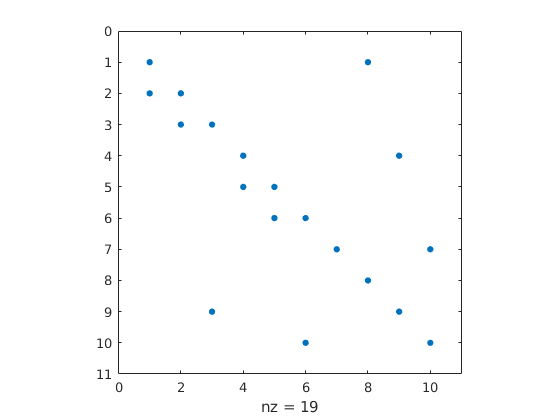

[A, u, g] = reorganize_fine_coarse(A, u, g, fc_ratio);
spy(A)


u = MGRIT(A, g, u, fc_ratio);

u = reverse_permute_fine_coarse(u, fc_ratio)

u =     1.0000
    2.0000
    3.0000
    4.0000
    5.0000
    6.0000
    7.0000
    8.0000
    9.0000
   11.5434


u = permute_fine_coarse(u, fc_ratio);

u = MGRIT(A, g, u, fc_ratio);

u = reverse_permute_fine_coarse(u, fc_ratio)

u =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10
